## 3.1a

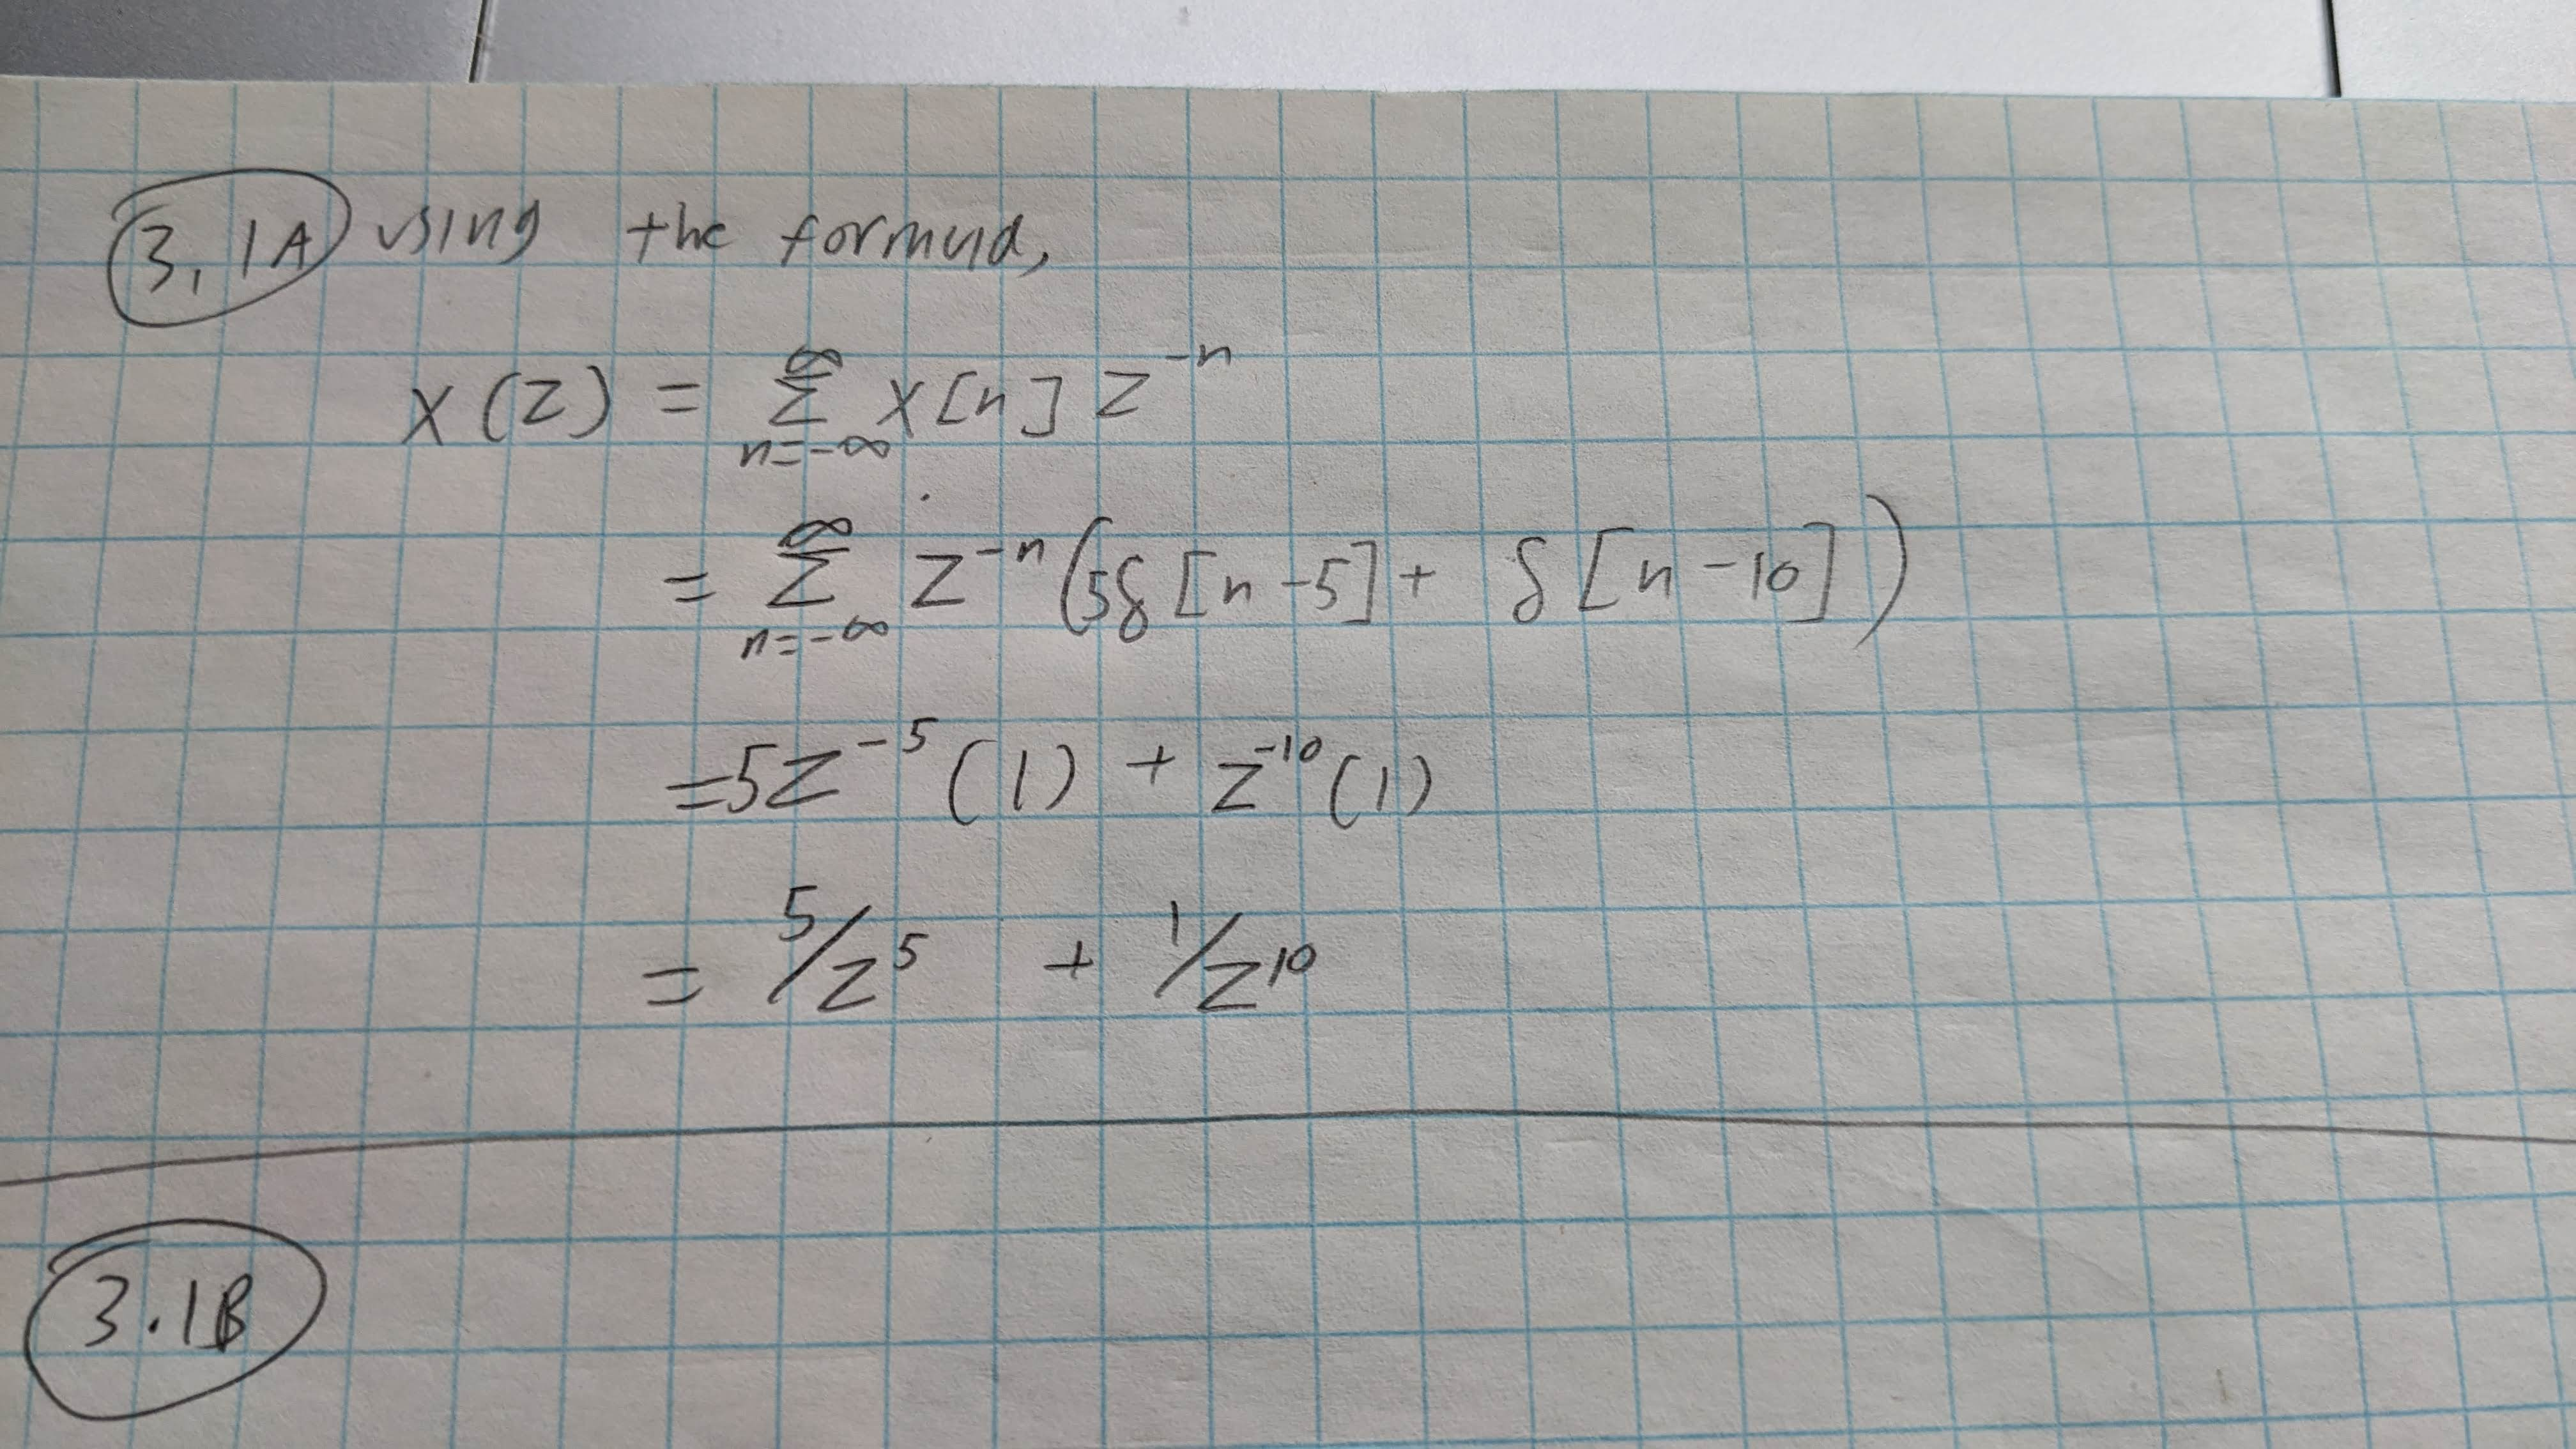

Code portion:

The main issue is that we cannot use the dirac() and heaviside functions for our purposes, as they use a different definition from the one used for DSP in this course. We will therefore need to make our own.

%set heaviside to what is used in course (0 to 1 instantly after n crosses origin, with no 1/2)
oldparam = sympref("HeavisideAtOrigin",0);

%set symbolic variable
syms n

%we use kronecker delta so that impulse shoots up to 1 rather than infinity
x = 5*kroneckerDelta(n-5) + kroneckerDelta(n-10)

$$x = 5\,\delta_{n-5,0}+\delta_{n-10,0}$$

X = ztrans(x)

$$X = \frac{5}{z^{5}}+\frac{1}{z^{10}}$$

## 3.1b

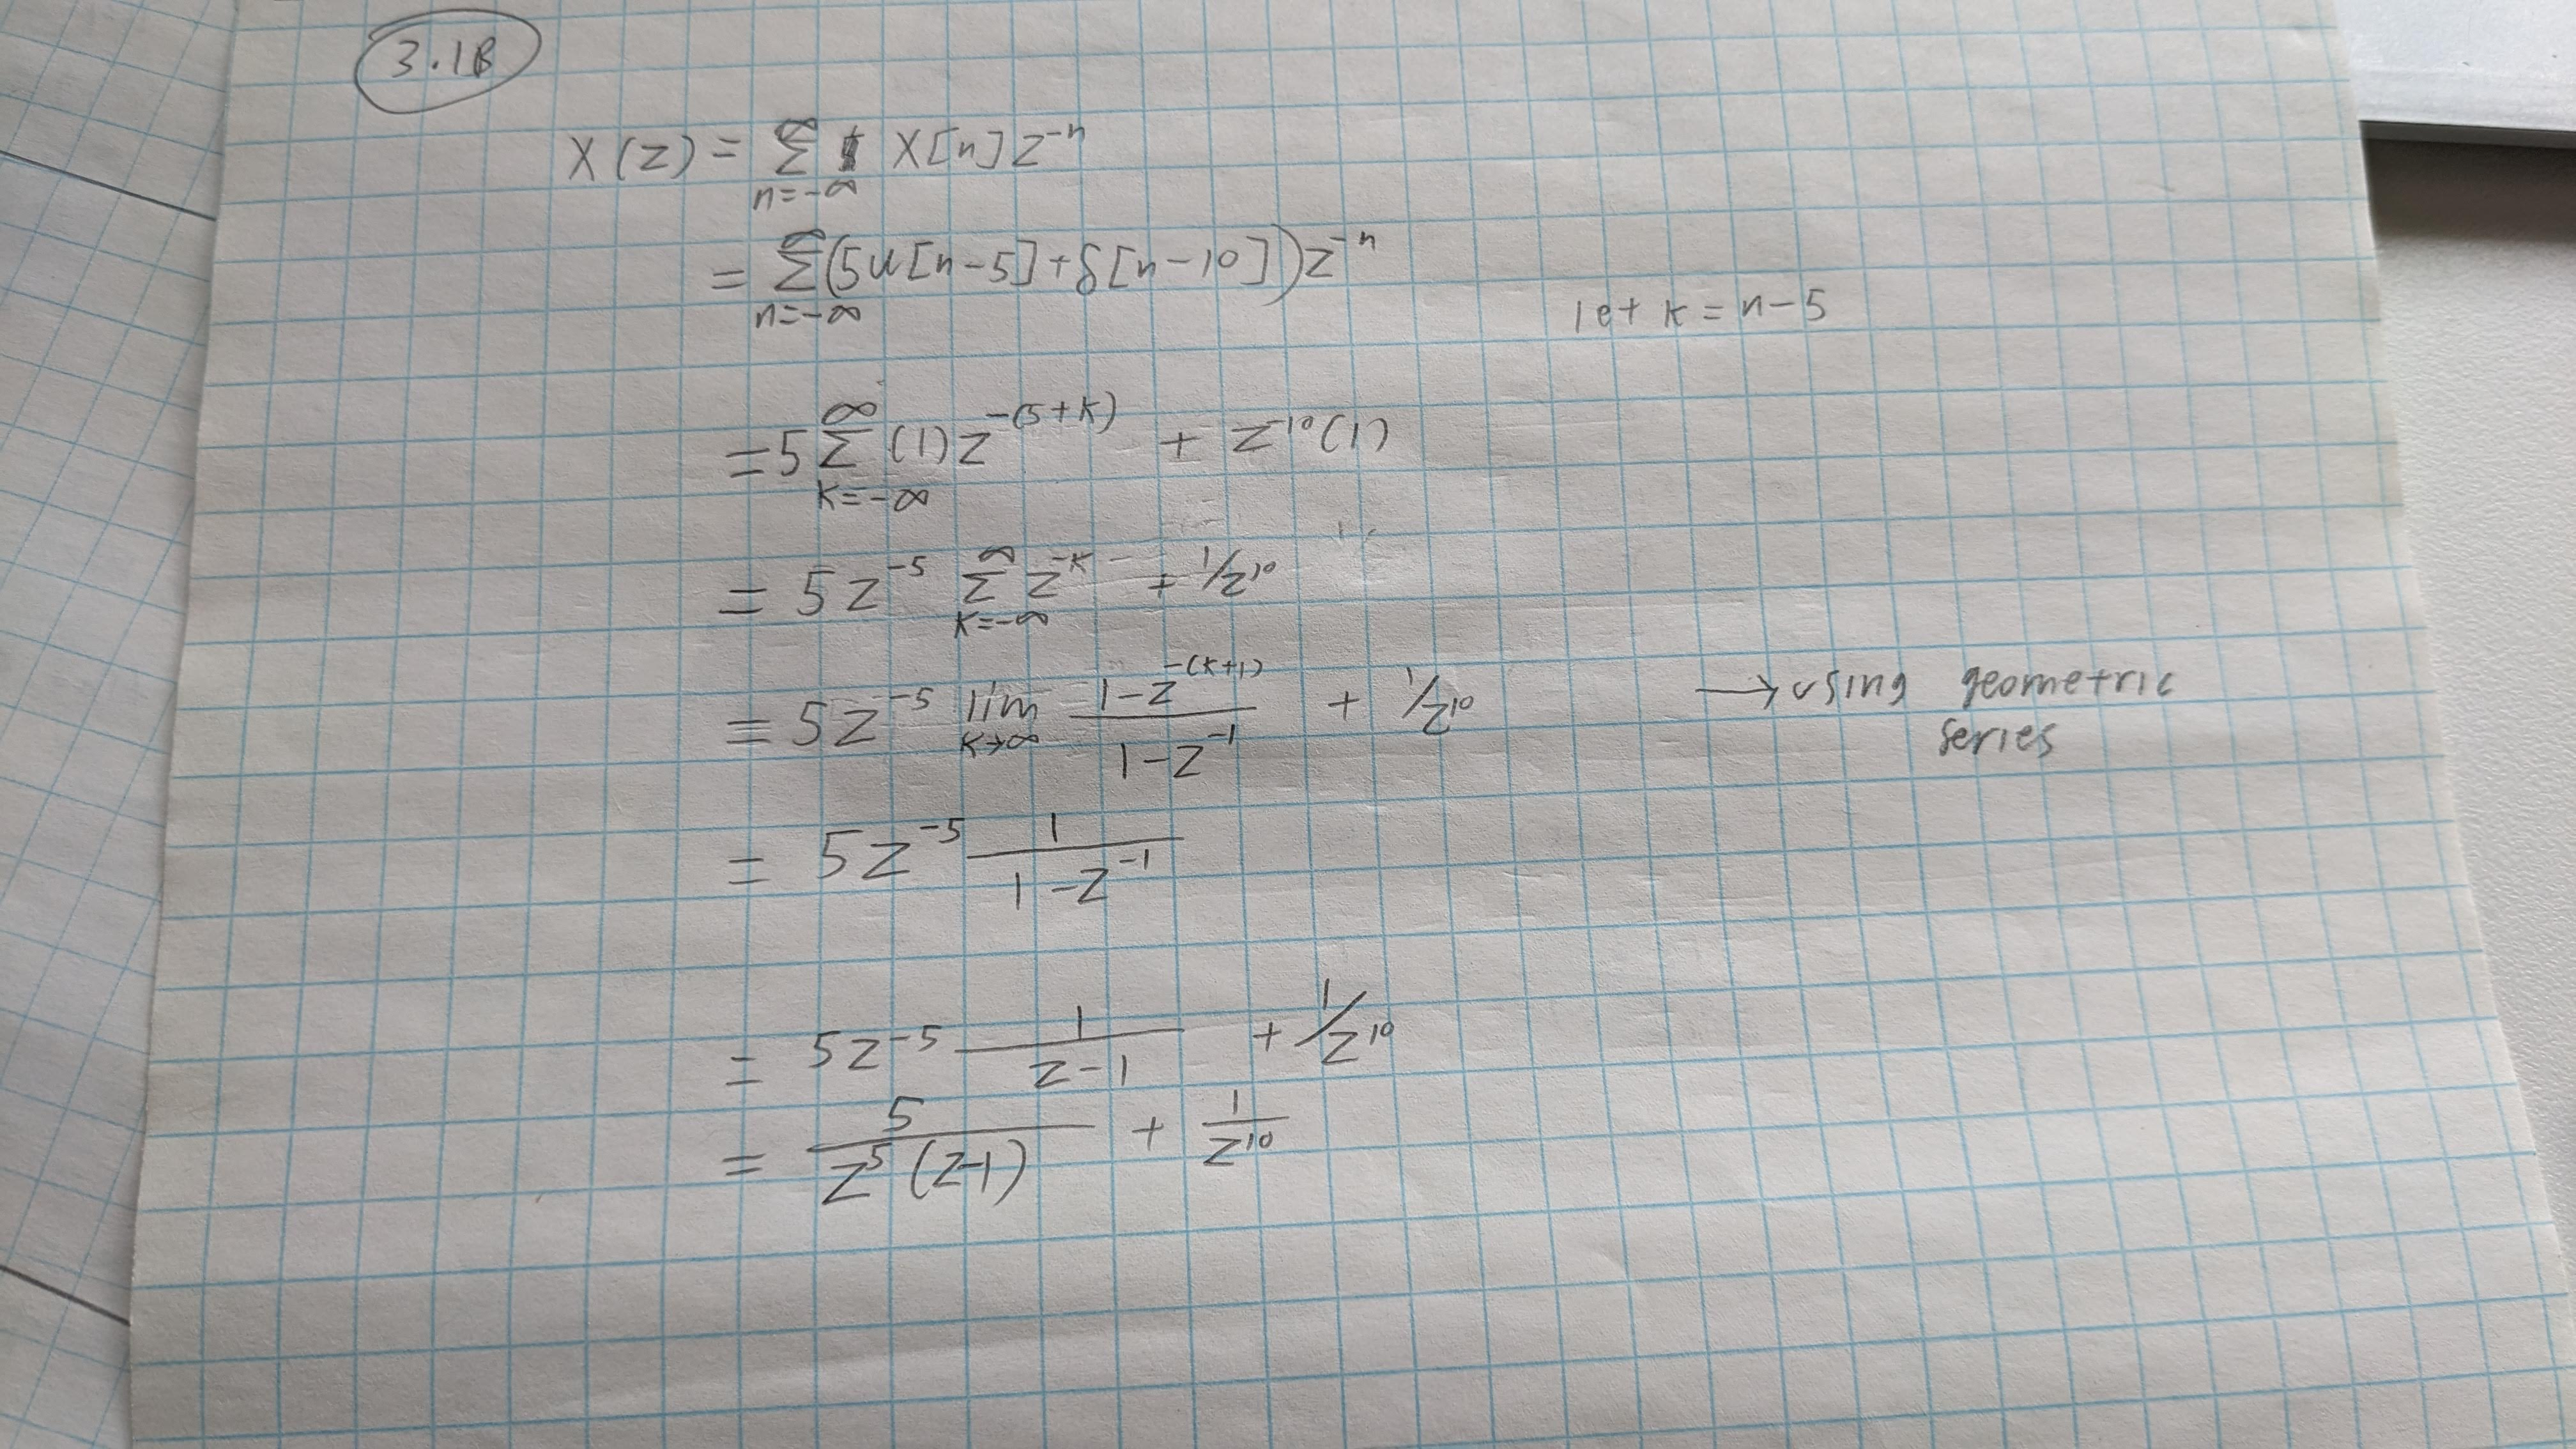

Code section:

x = 5*heaviside(n-5) + kroneckerDelta(n-10)

$$x = 5\,\mathrm{heaviside}\left(n-5\right)+\delta_{n-10,0}$$

X = ztrans(x)

$$X = \frac{5}{z^{5}\,\left(z-1\right)}+\frac{1}{z^{10}}$$

## 3.1c

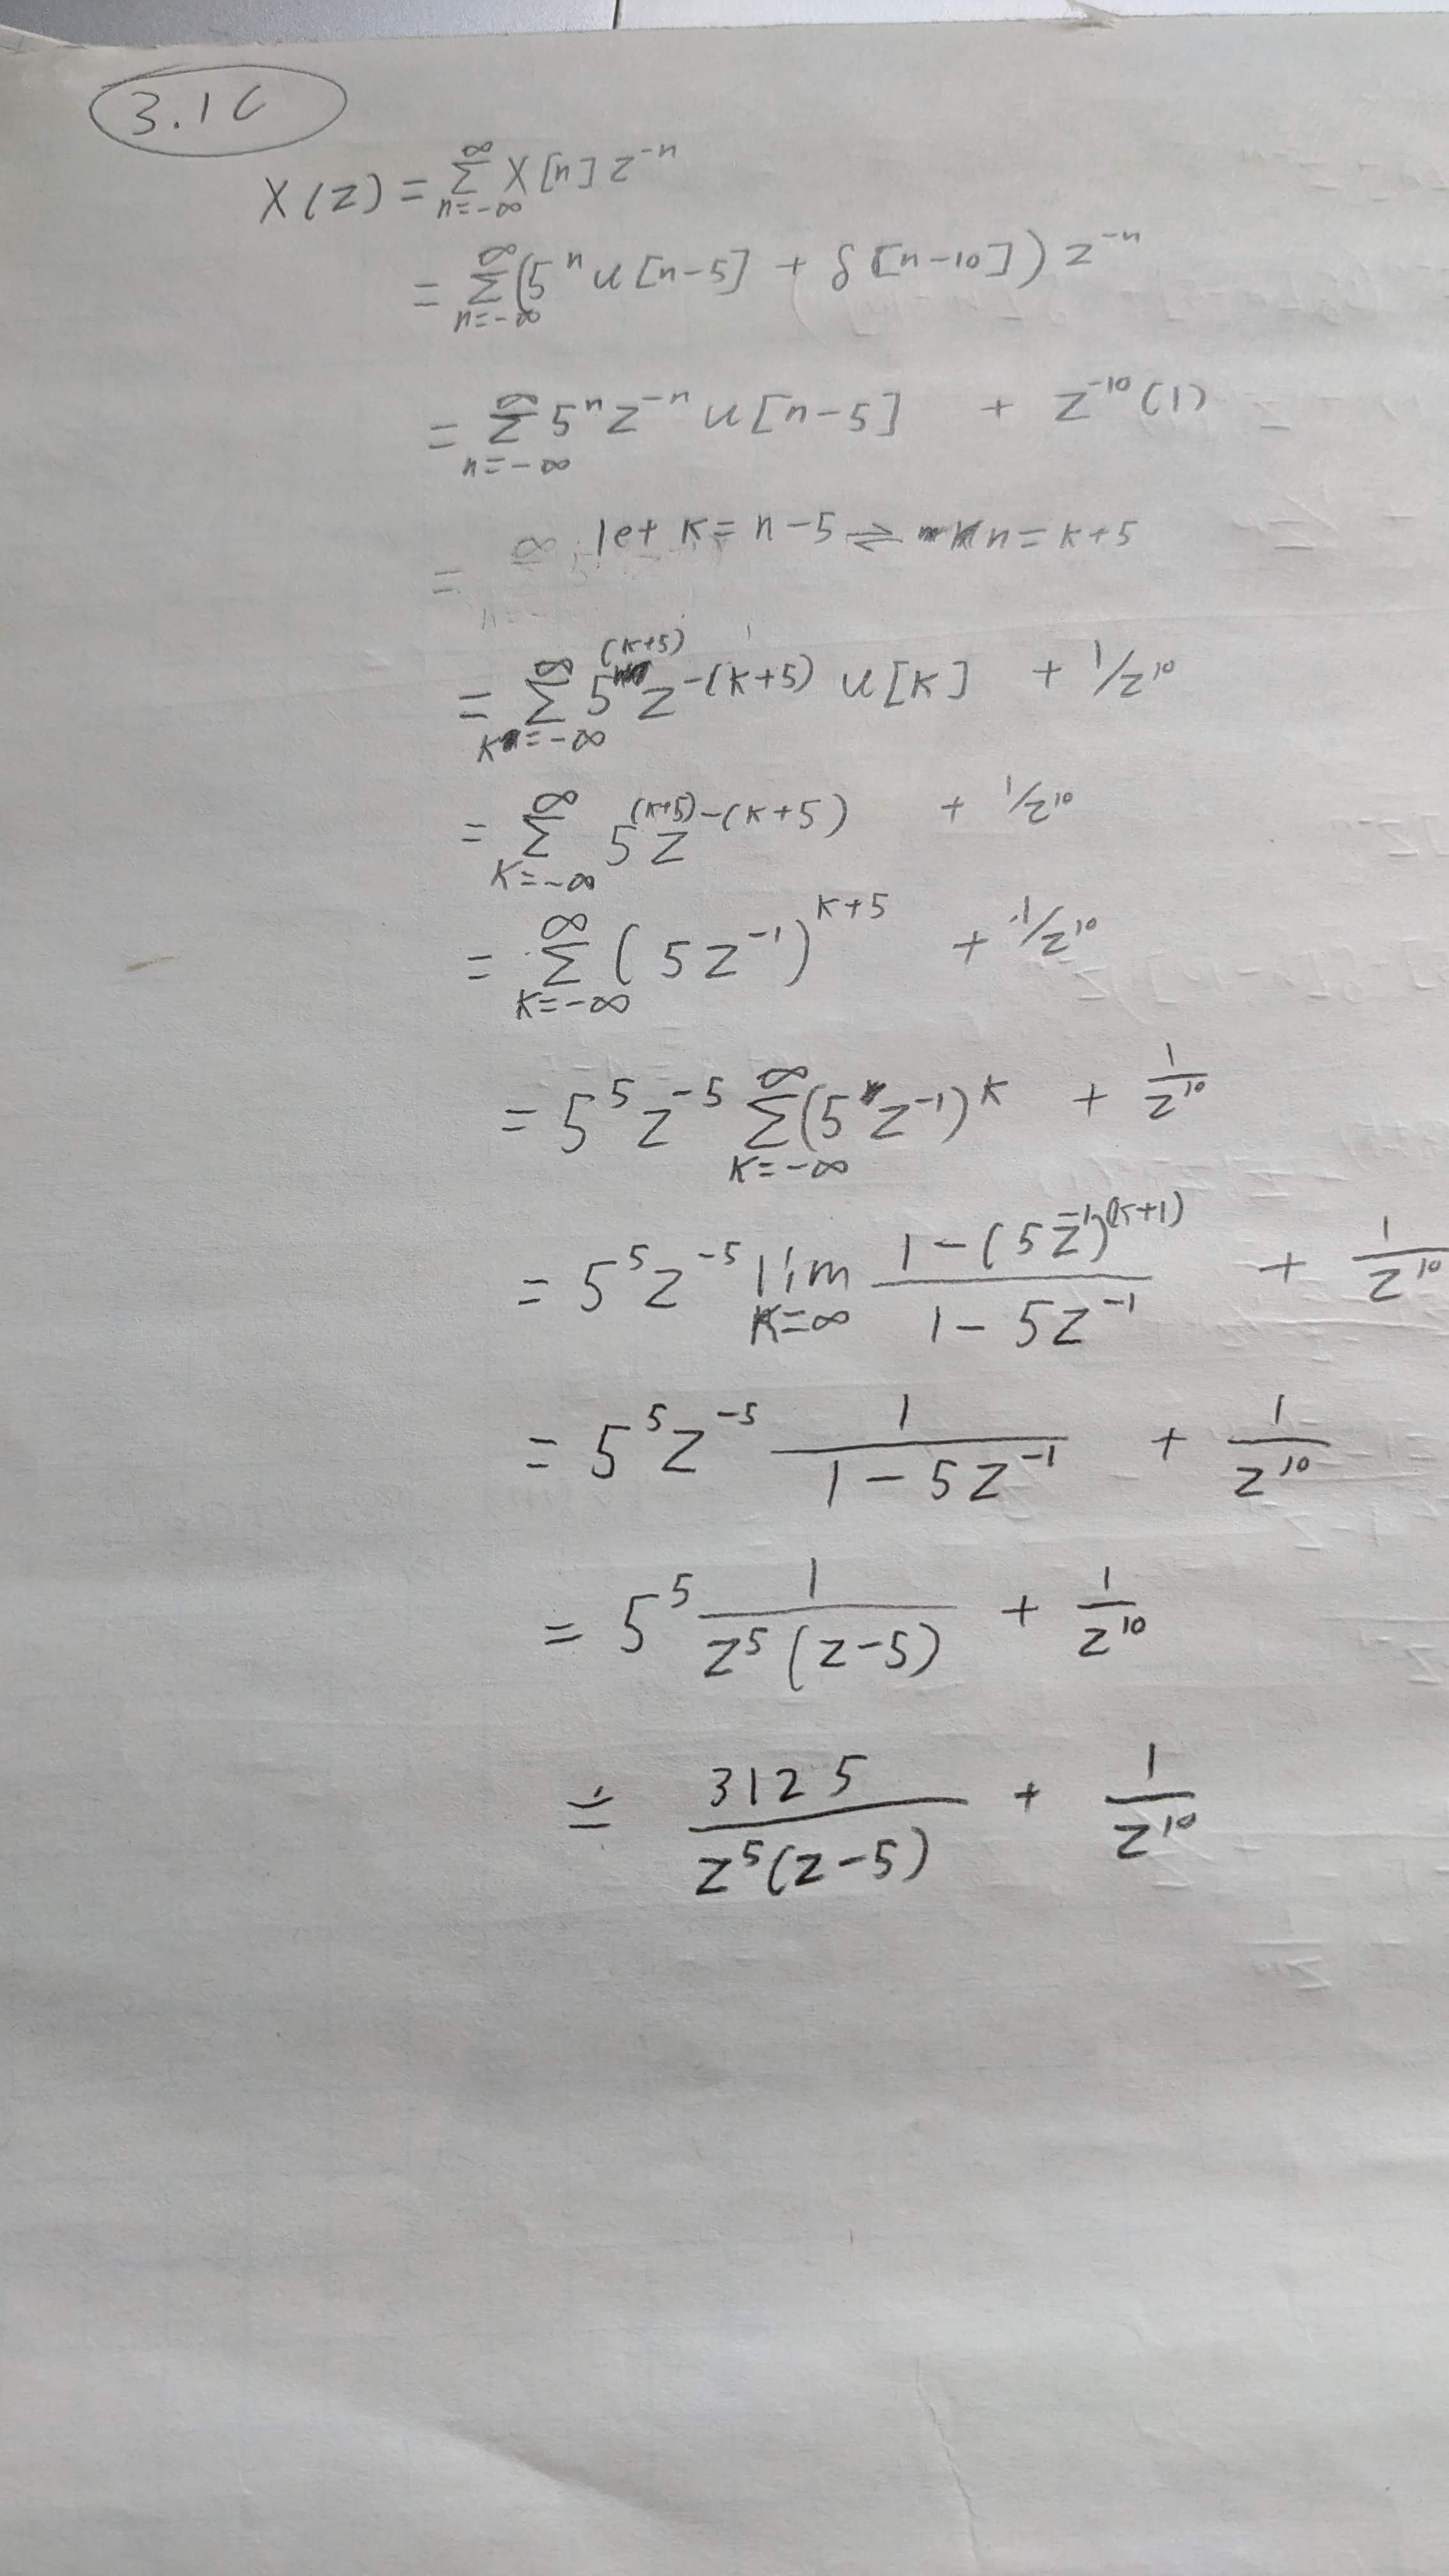

Code Section:

%MATLAB has strange behaviour when heaviside at origin set to 0. in order
%to get correct statement, you need to set it as 5^(n-1) rather than 5^n
x = (5^n)*heaviside(n-5) + kroneckerDelta(n-10)

$$x = \delta_{n-10,0}+5^{n}\,\mathrm{heaviside}\left(n-5\right)$$

X = ztrans(x)

$$X = \frac{15625}{z^{5}\,\left(z-5\right)}+\frac{1}{z^{10}}$$


%this code below should have correct output
x = (5^(n-1))*heaviside(n-5) + kroneckerDelta(n-10);
X = ztrans(x);

## 3.2a, 3.2b:

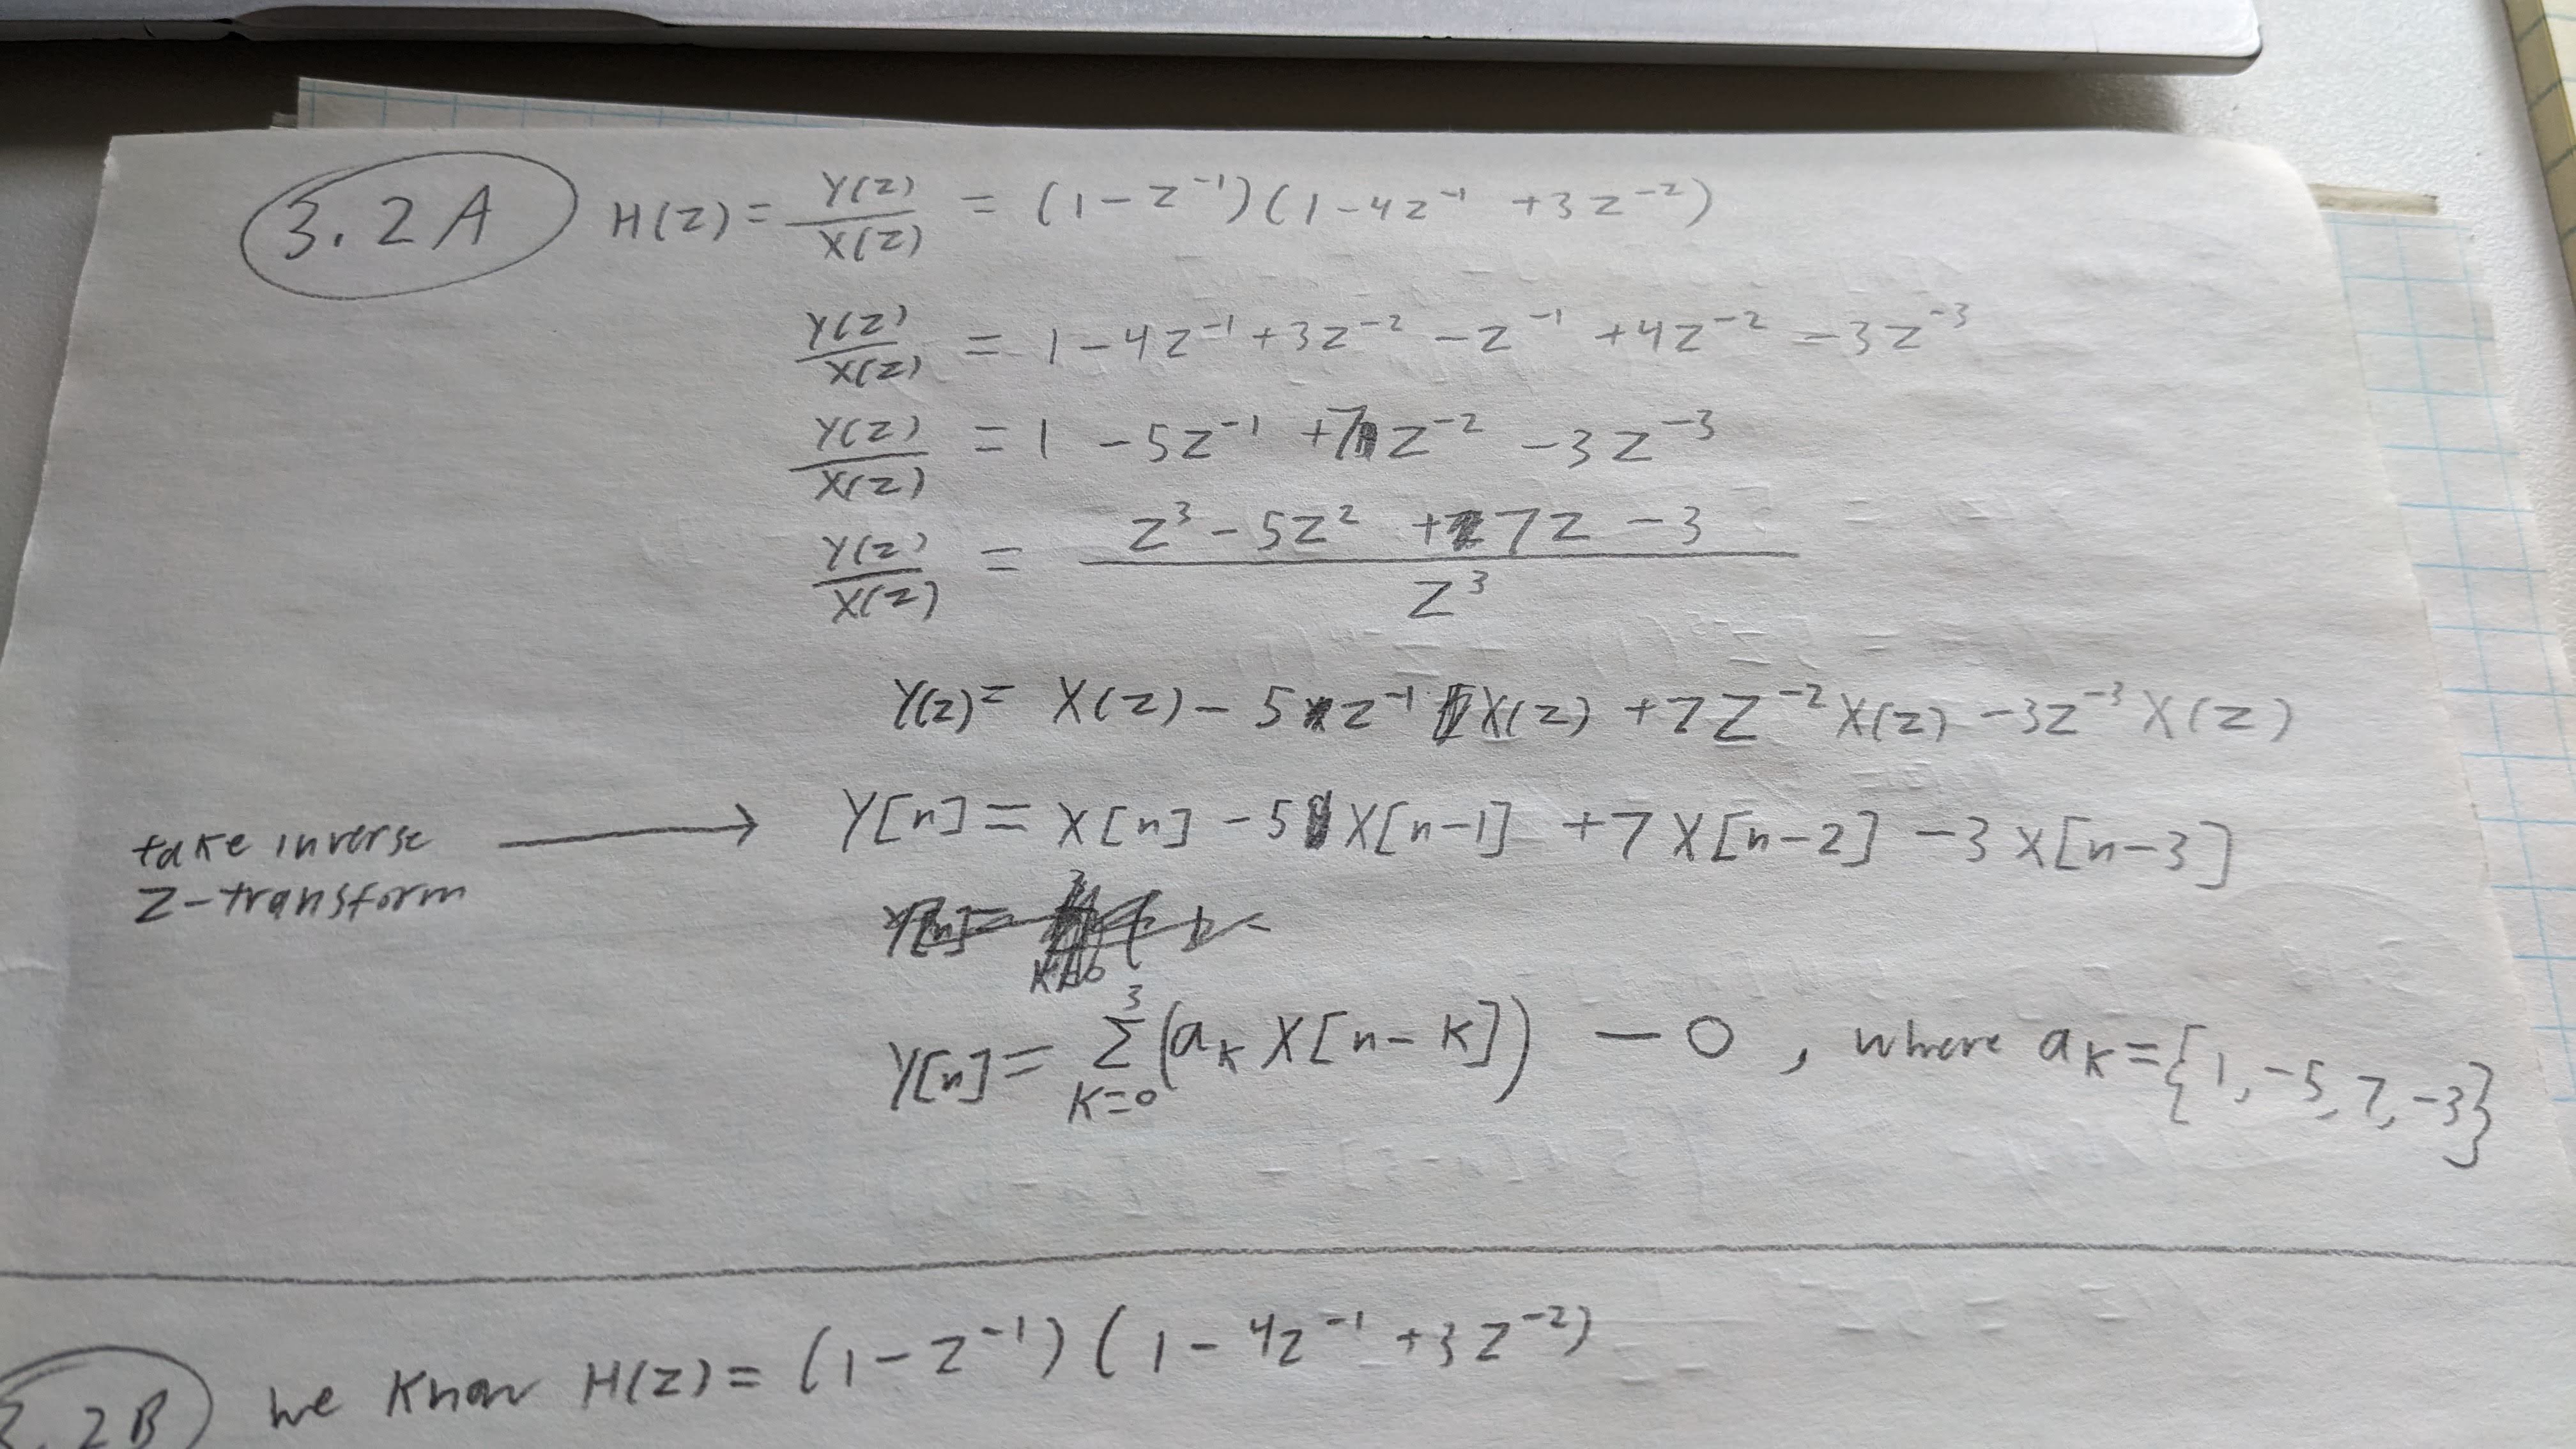

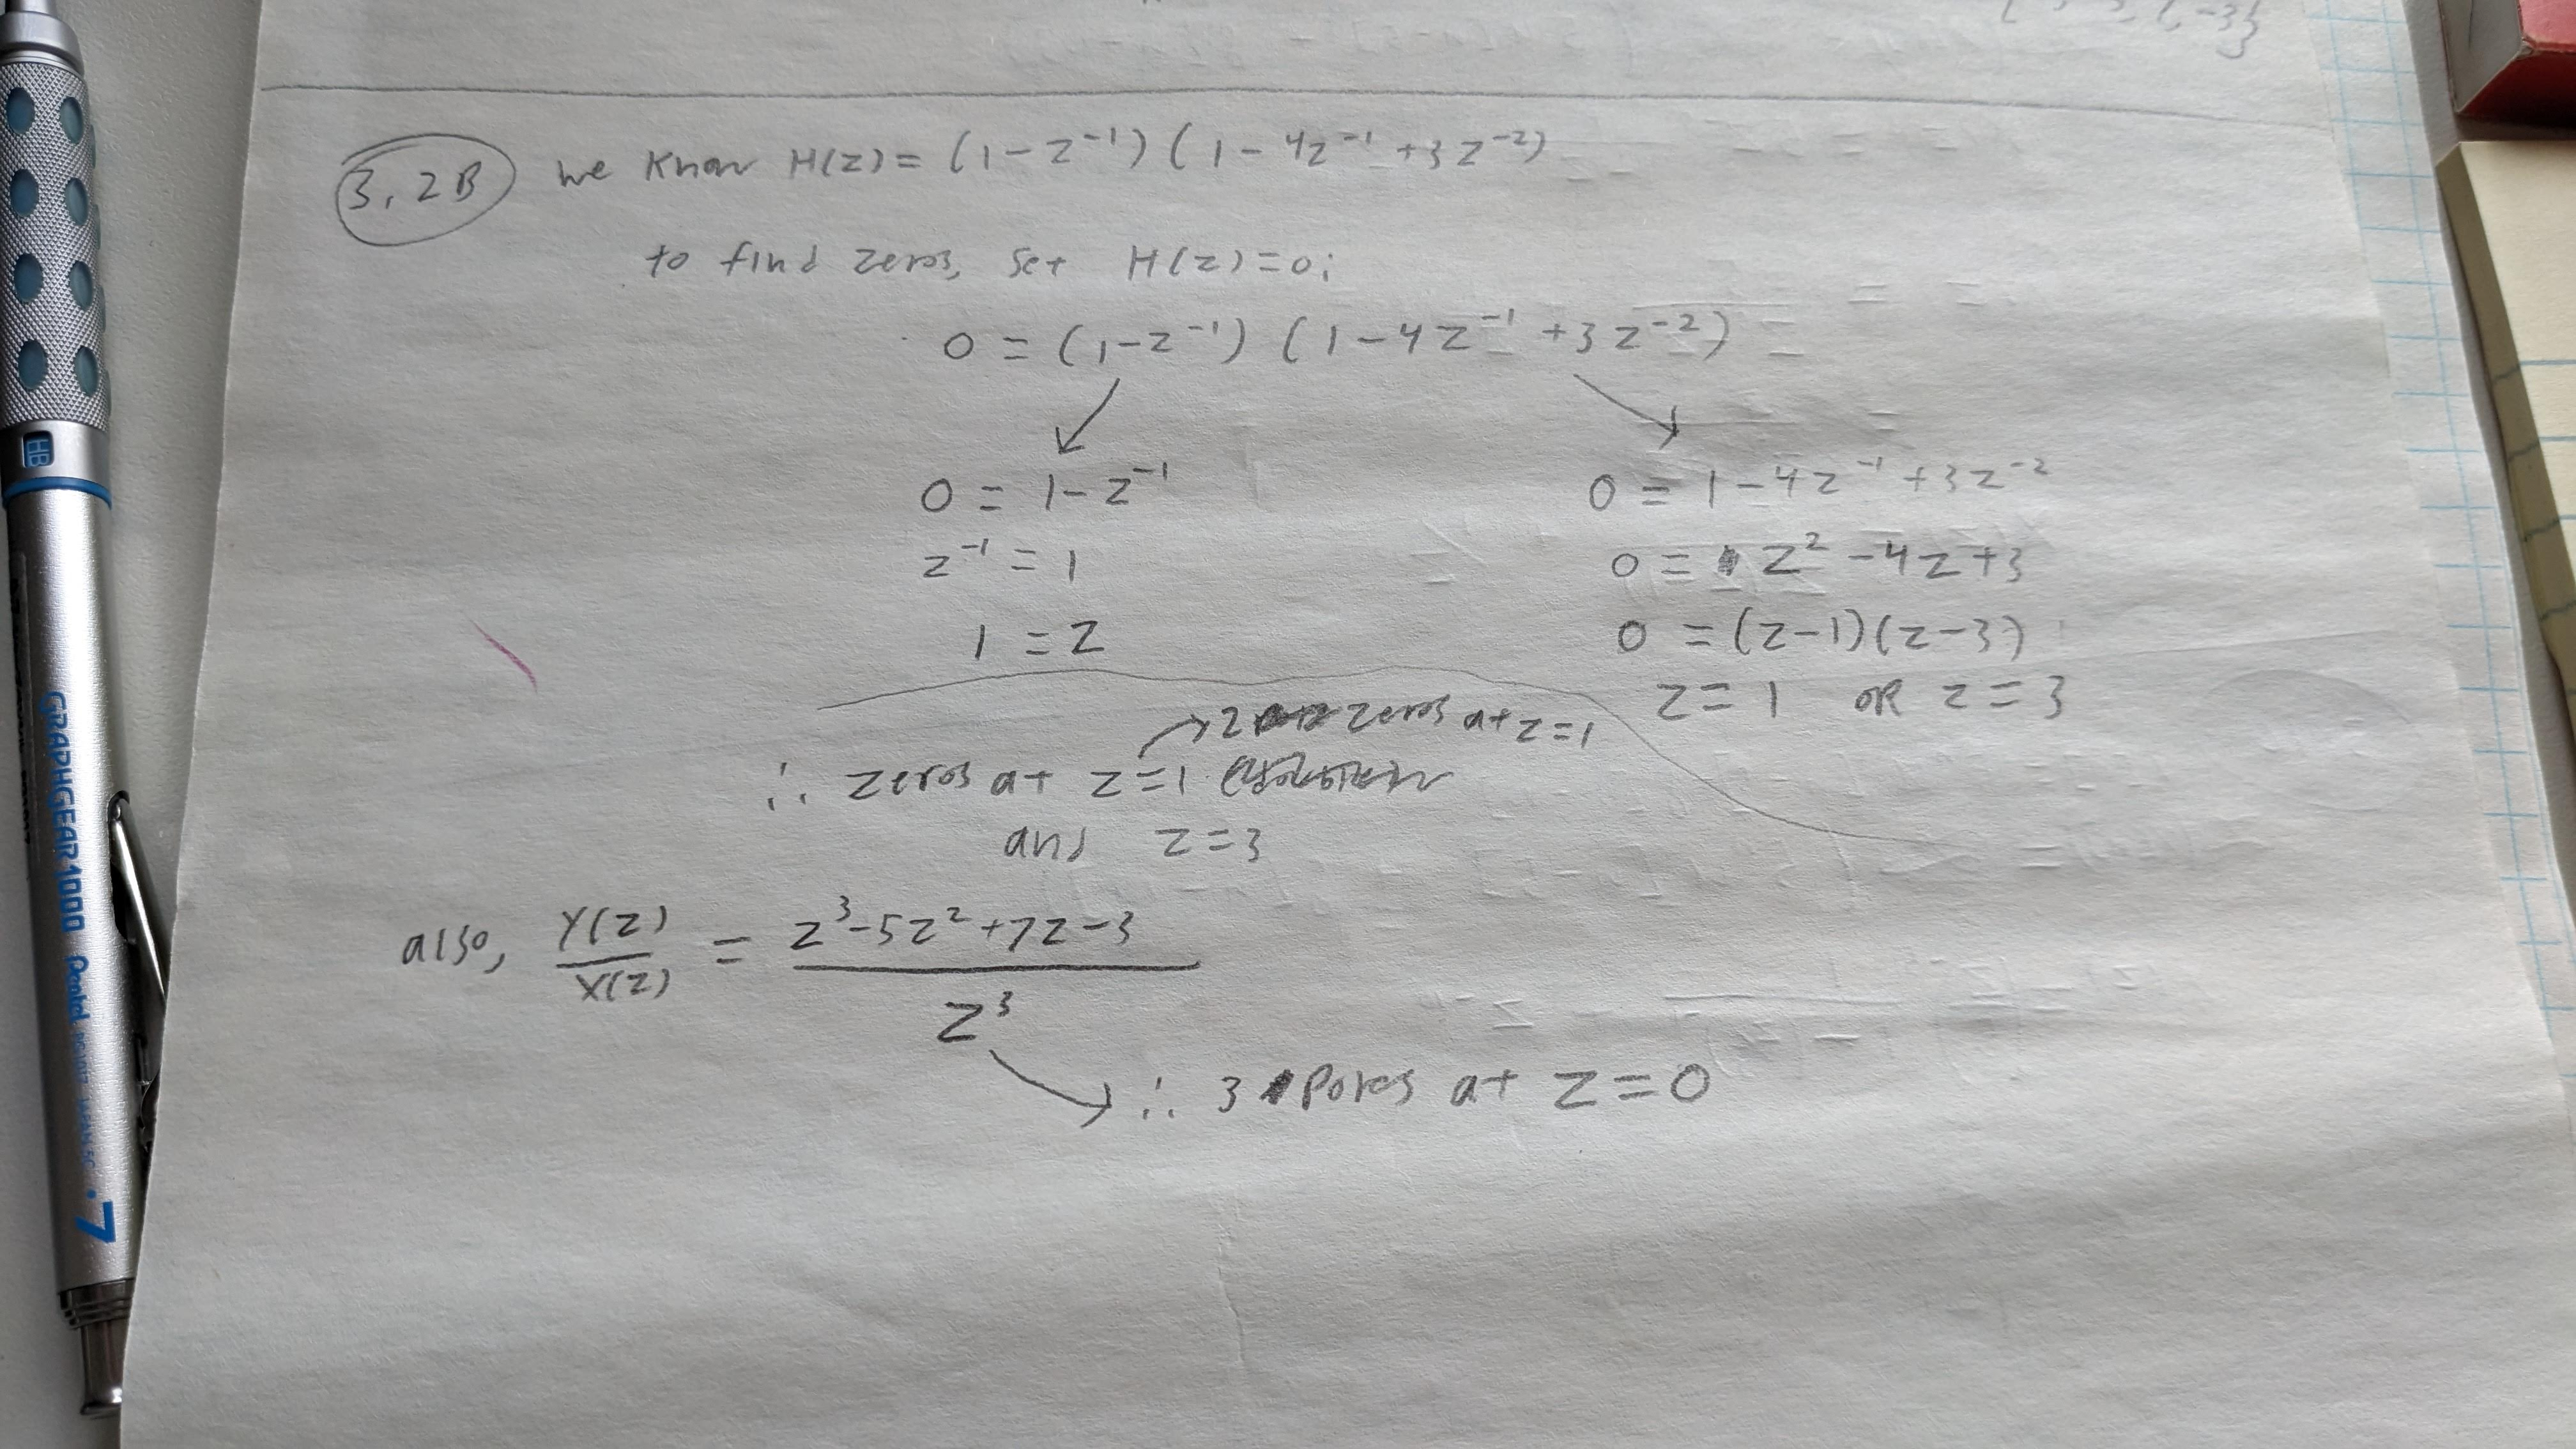

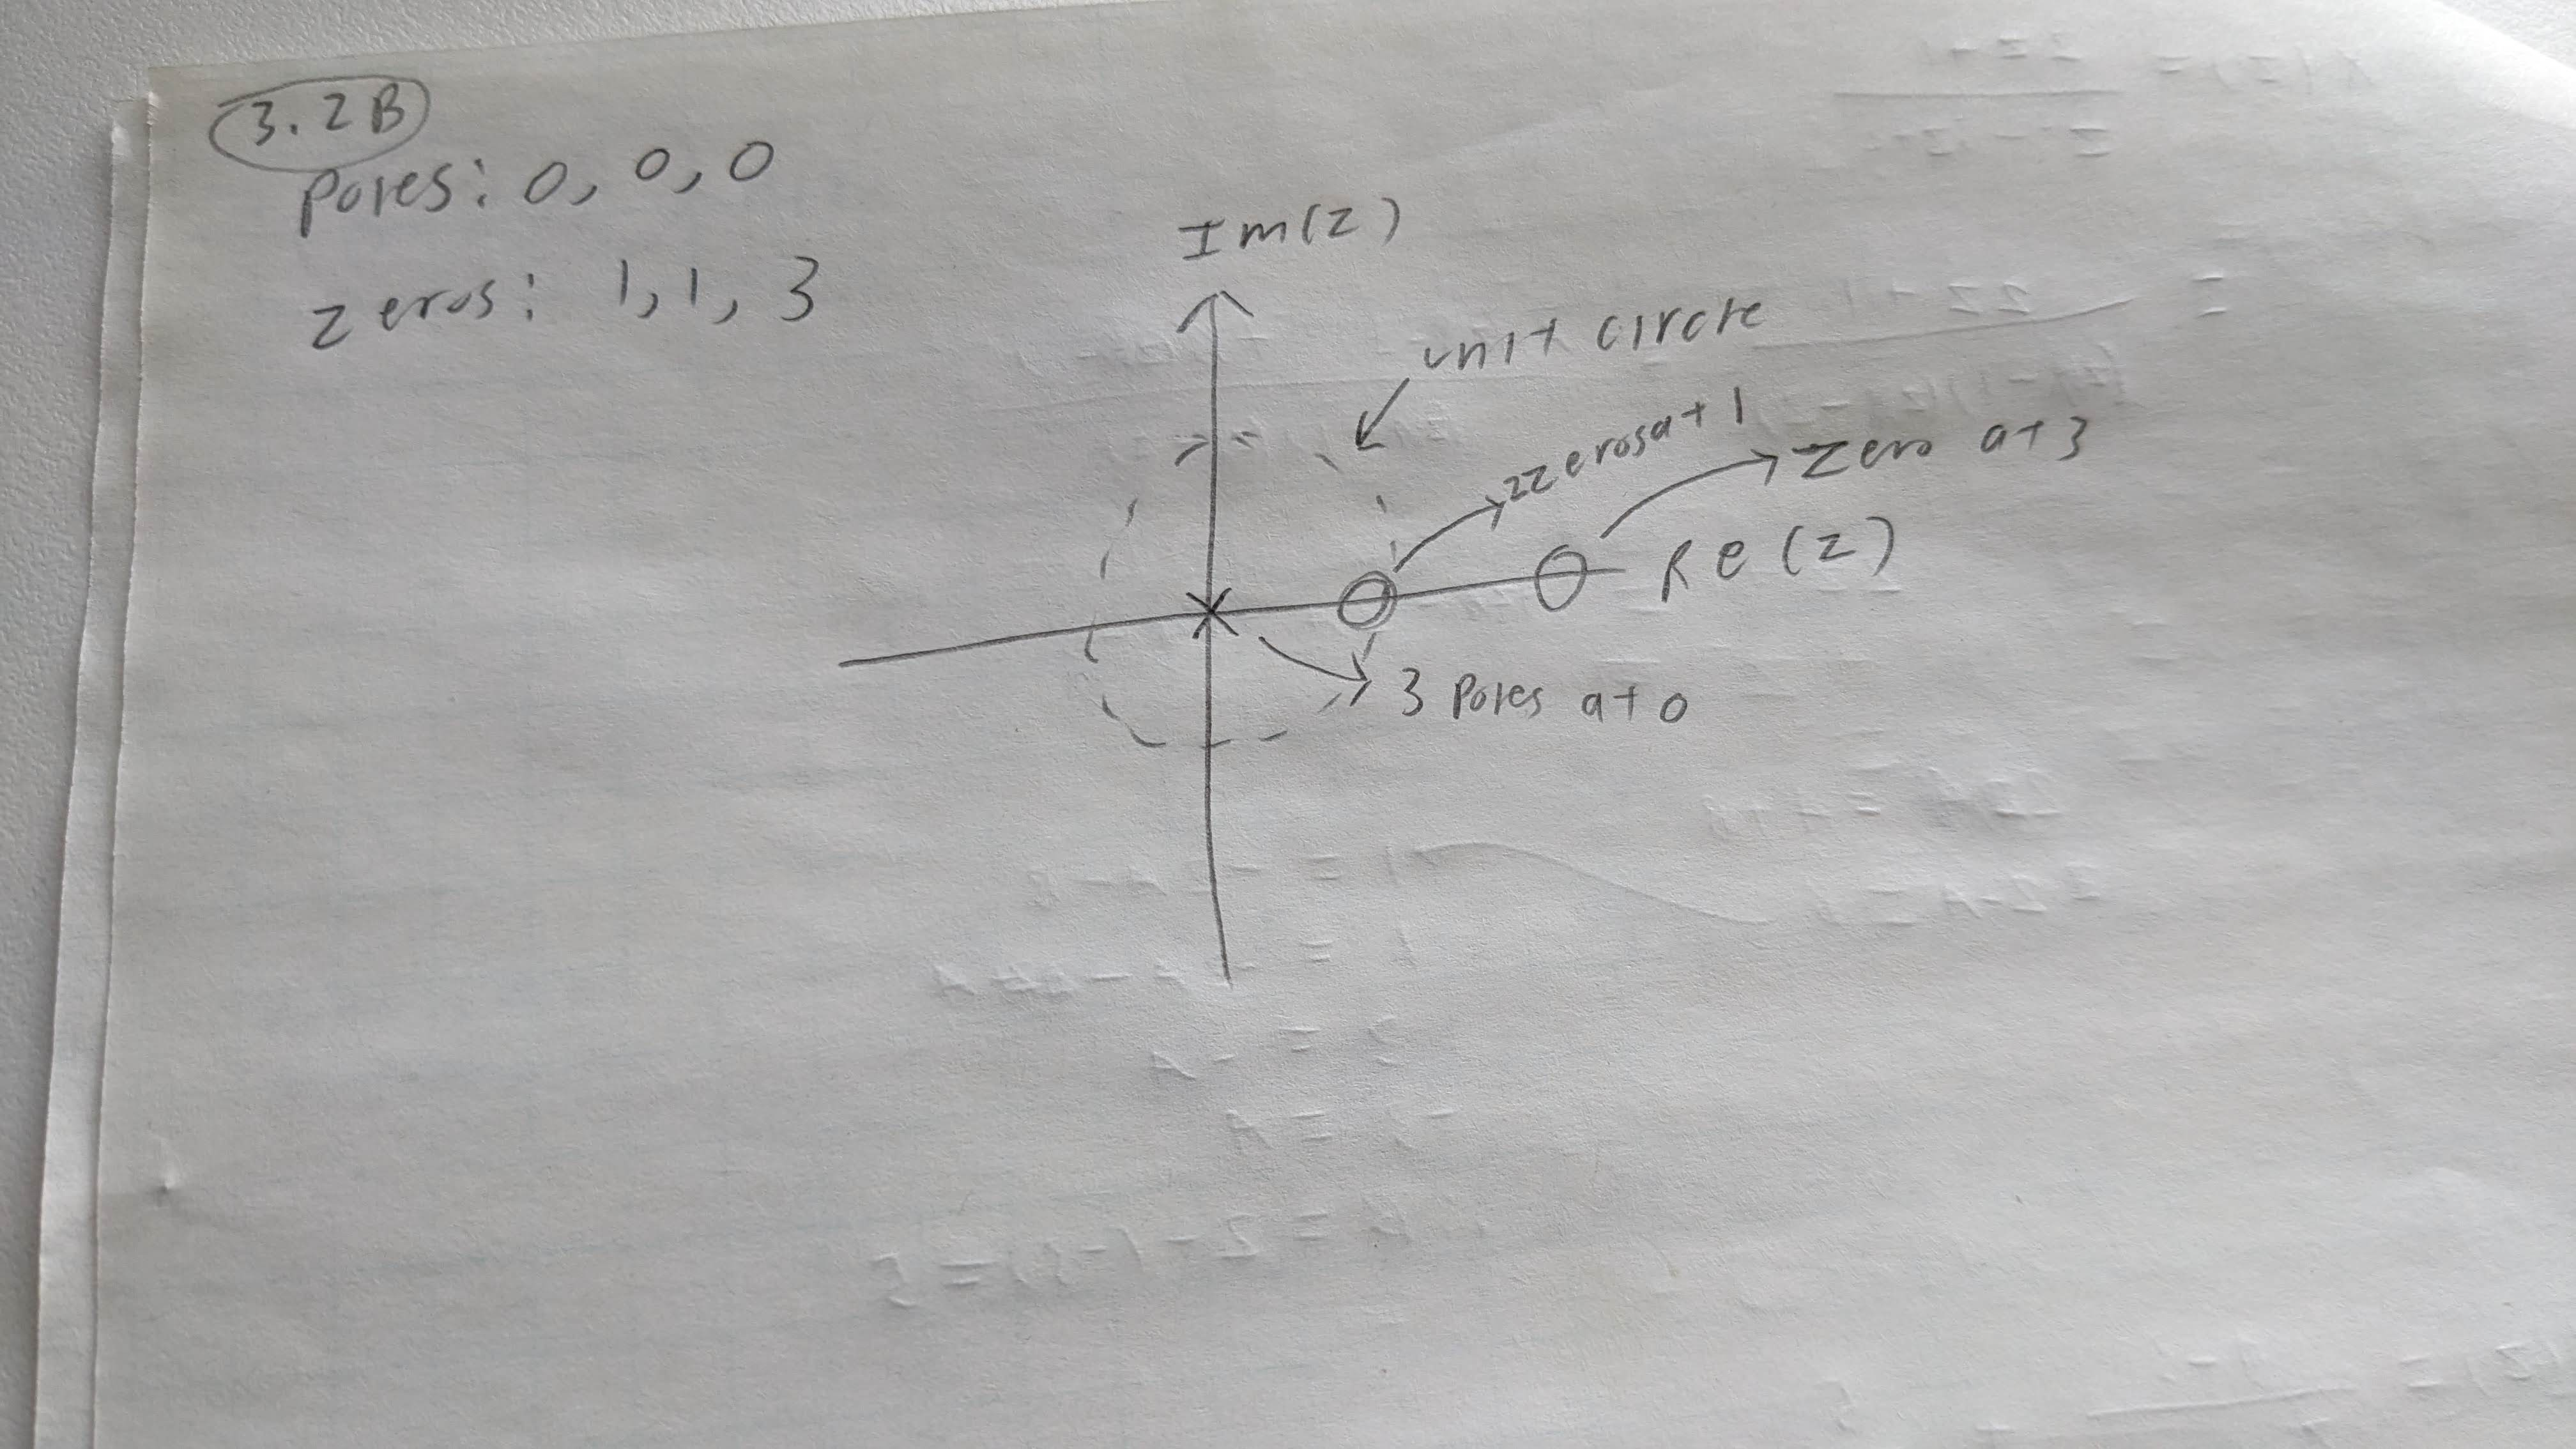

## 3.2c

We will first check the difference equation:

syms z
%set transfer function and difference equation in z-domain
X = z^3

$$X = z^{3}$$

%Y = z^3 - 5*z^2 + 7*z - 3
Y = (1 -5*z^-1 + 7*z^-2 - 3*z^-3)*X

$$Y = -z^{3}\,\left(\frac{5}{z}-\frac{7}{z^{2}}+\frac{3}{z^{3}}-1\right)$$

H = (1 - z^-1)*(1 - 4*z^-1 + 3*z^-2)

$$H = -\left(\frac{1}{z}-1\right)\,\left(\frac{3}{z^{2}}-\frac{4}{z}+1\right)$$

ratio_z = Y/X

$$ratio\_z = \frac{7}{z^{2}}-\frac{5}{z}-\frac{3}{z^{3}}+1$$


%verify transfer function in time domain
h = iztrans(H)

$$h = 7\,\delta_{n-2,0}-5\,\delta_{n-1,0}-3\,\delta_{n-3,0}+\delta_{n,0}$$

%now verify the difference equation
ratio_yx = iztrans(ratio_z)

$$ratio\_yx = 7\,\delta_{n-2,0}-5\,\delta_{n-1,0}-3\,\delta_{n-3,0}+\delta_{n,0}$$


%%Y(z)/X(z) and H(z) match.


As is shown, and y[n]/x[n] matches h[n],and therefore Y(z)/X(z) matches the transfer function H(z) verifying the difference equation.

We will now verify the poles and zeros:

[H_numerator,H_denominator] = numden(ratio_z)%extract numerator and denominator of H(z)

$$H\_numerator = z^{3}-5\,z^{2}+7\,z-3$$

$$H\_denominator = z^{3}$$

H_zeros = roots(sym2poly(H_numerator)) %list out zeros of H(z)

H_zeros =    3.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i


H_poles = roots(sym2poly(H_denominator)) %list out poles of H(z)

H_poles =      0
     0
     0


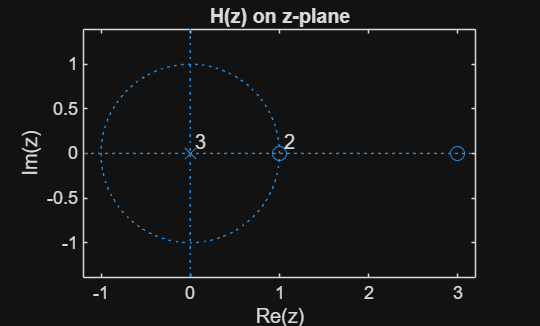


zplane(H_zeros,H_poles)
xlabel("Re(z)")
ylabel("Im(z)")
title("H(z) on z-plane")

As can be seen, the poles, zeros, and time-domain function found via code match with what was manually found.

## 3.3a

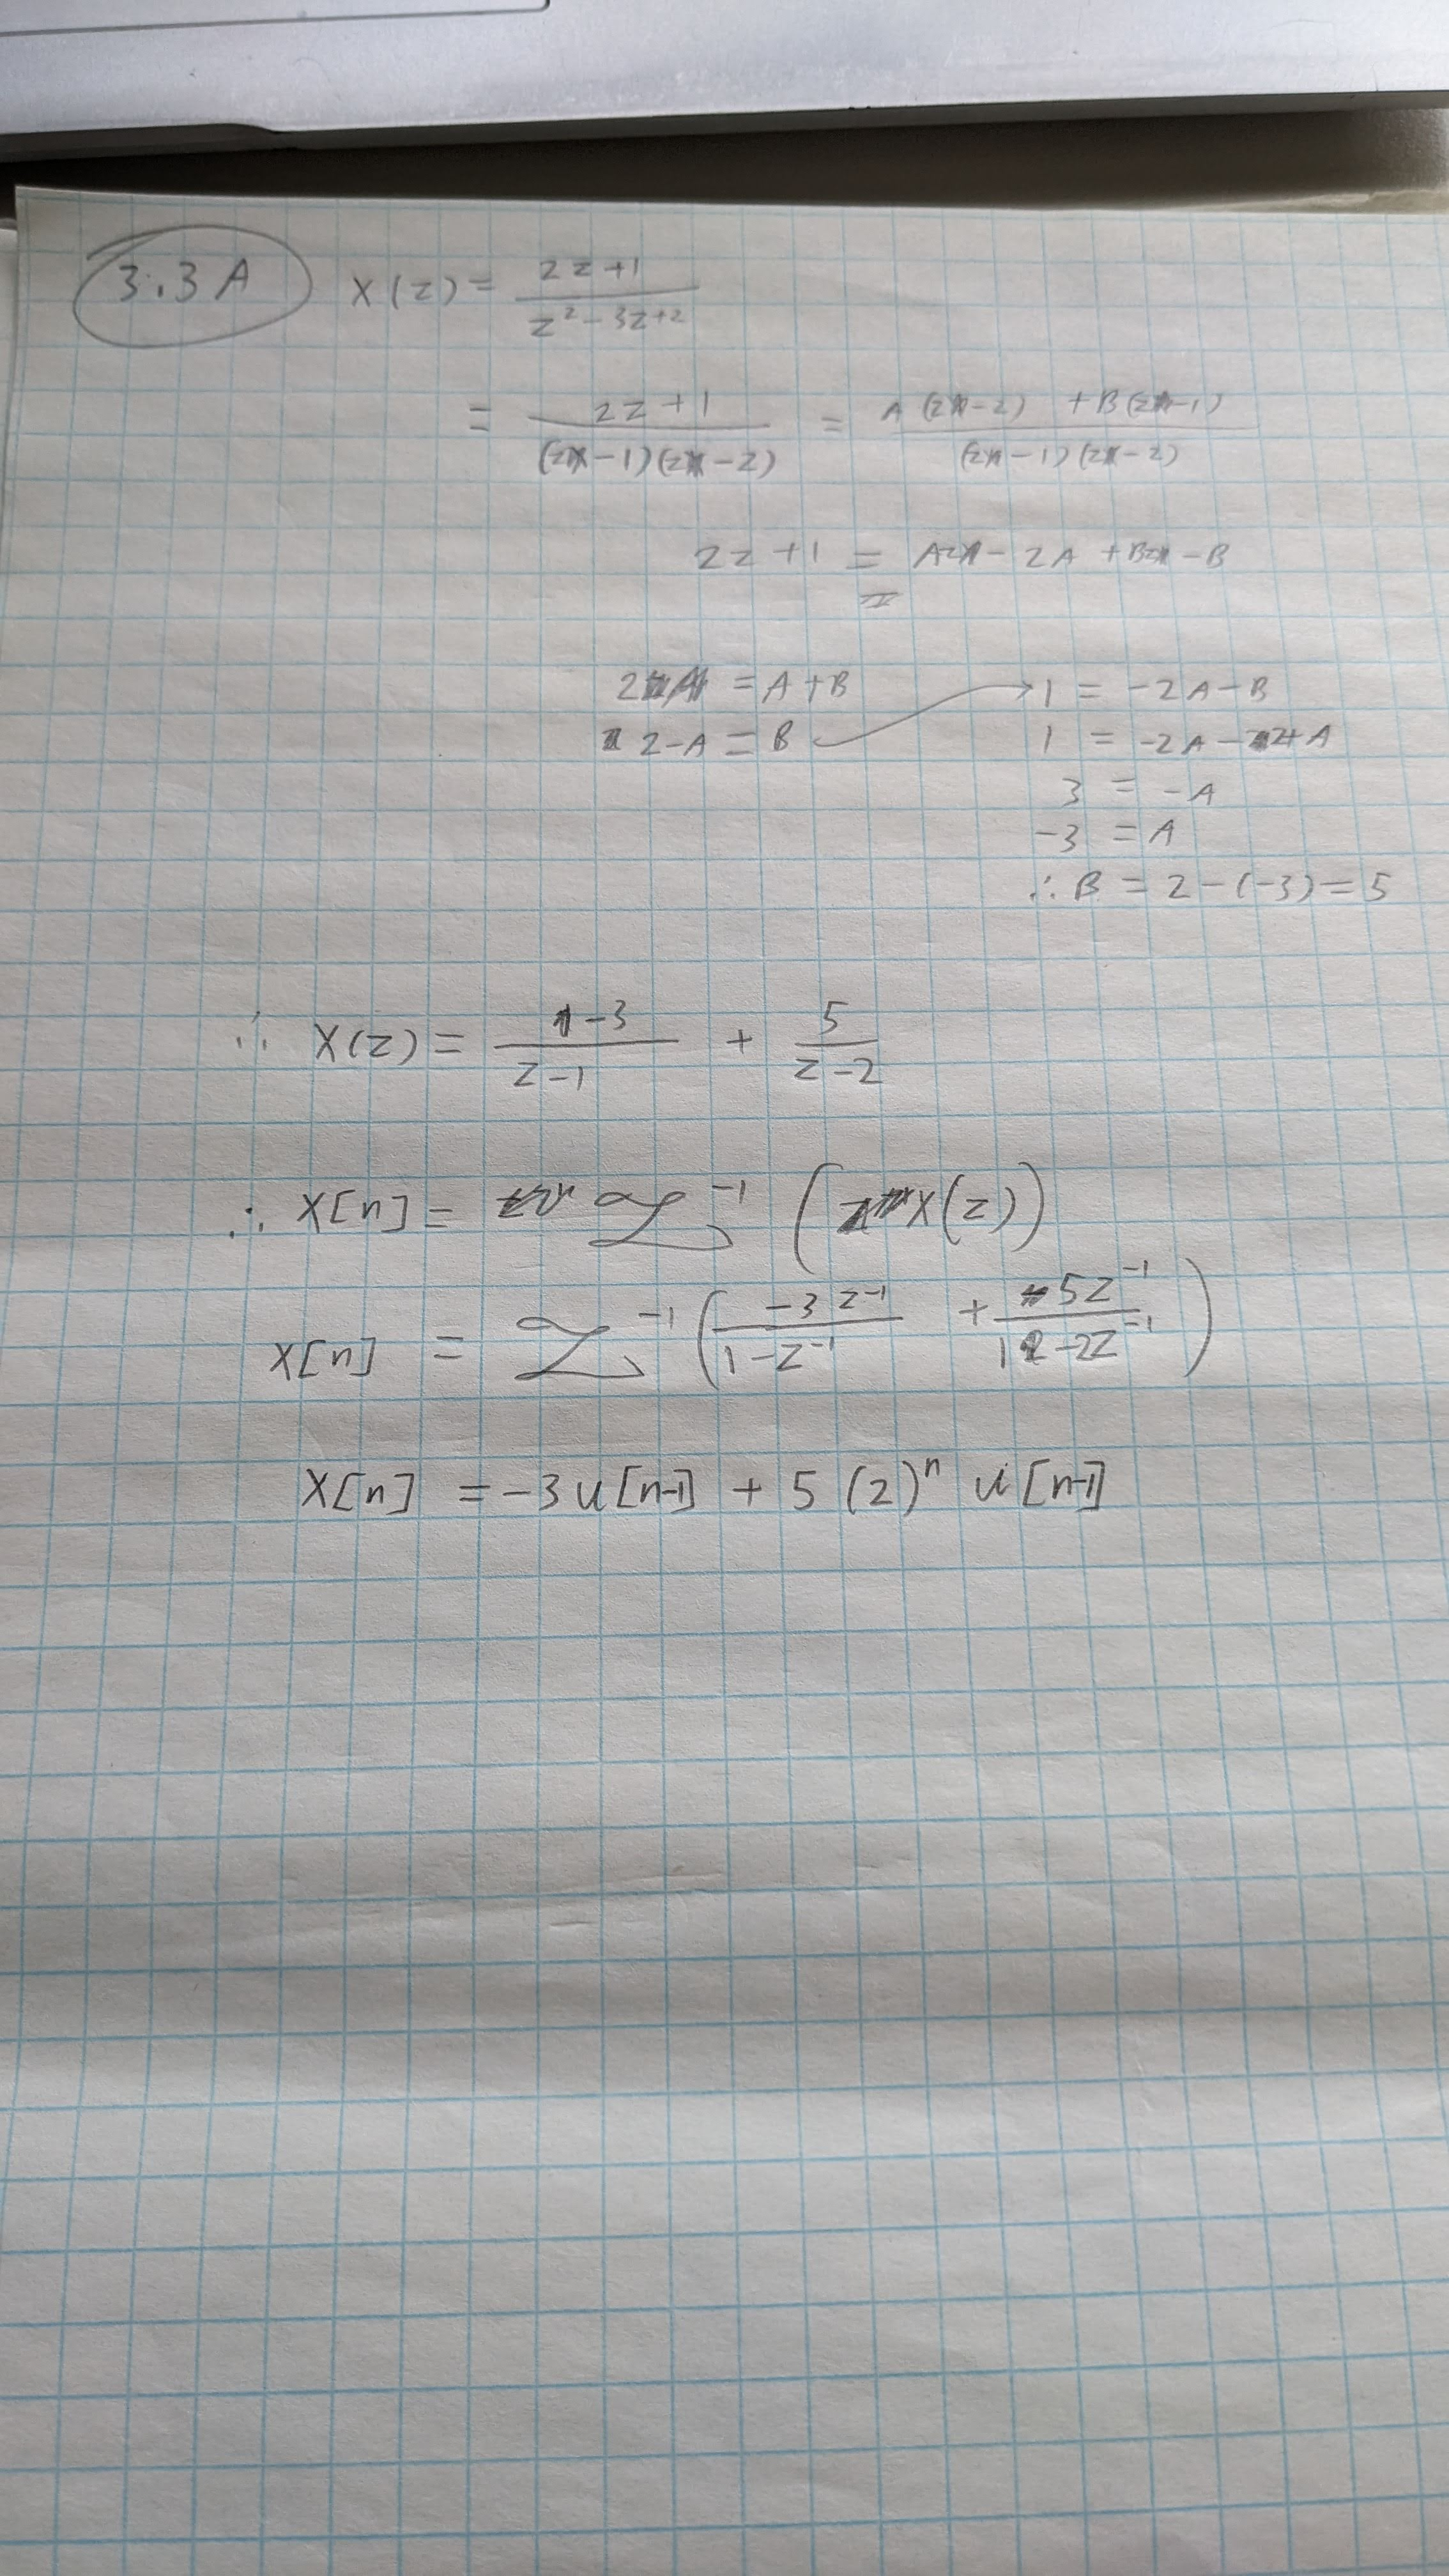

Code Section:

X = (2*z+1)/(z^2 - 3*z +2)%set z-domain X(z)

$$X = \frac{2\,z+1}{z^{2}-3\,z+2}$$

X = partfrac(X)

$$X = \frac{5}{z-2}-\frac{3}{z-1}$$

x = iztrans(X)

$$x = \frac{5\,2^{n}}{2}+\frac{\delta_{n,0}}{2}-3$$

## 3.3b

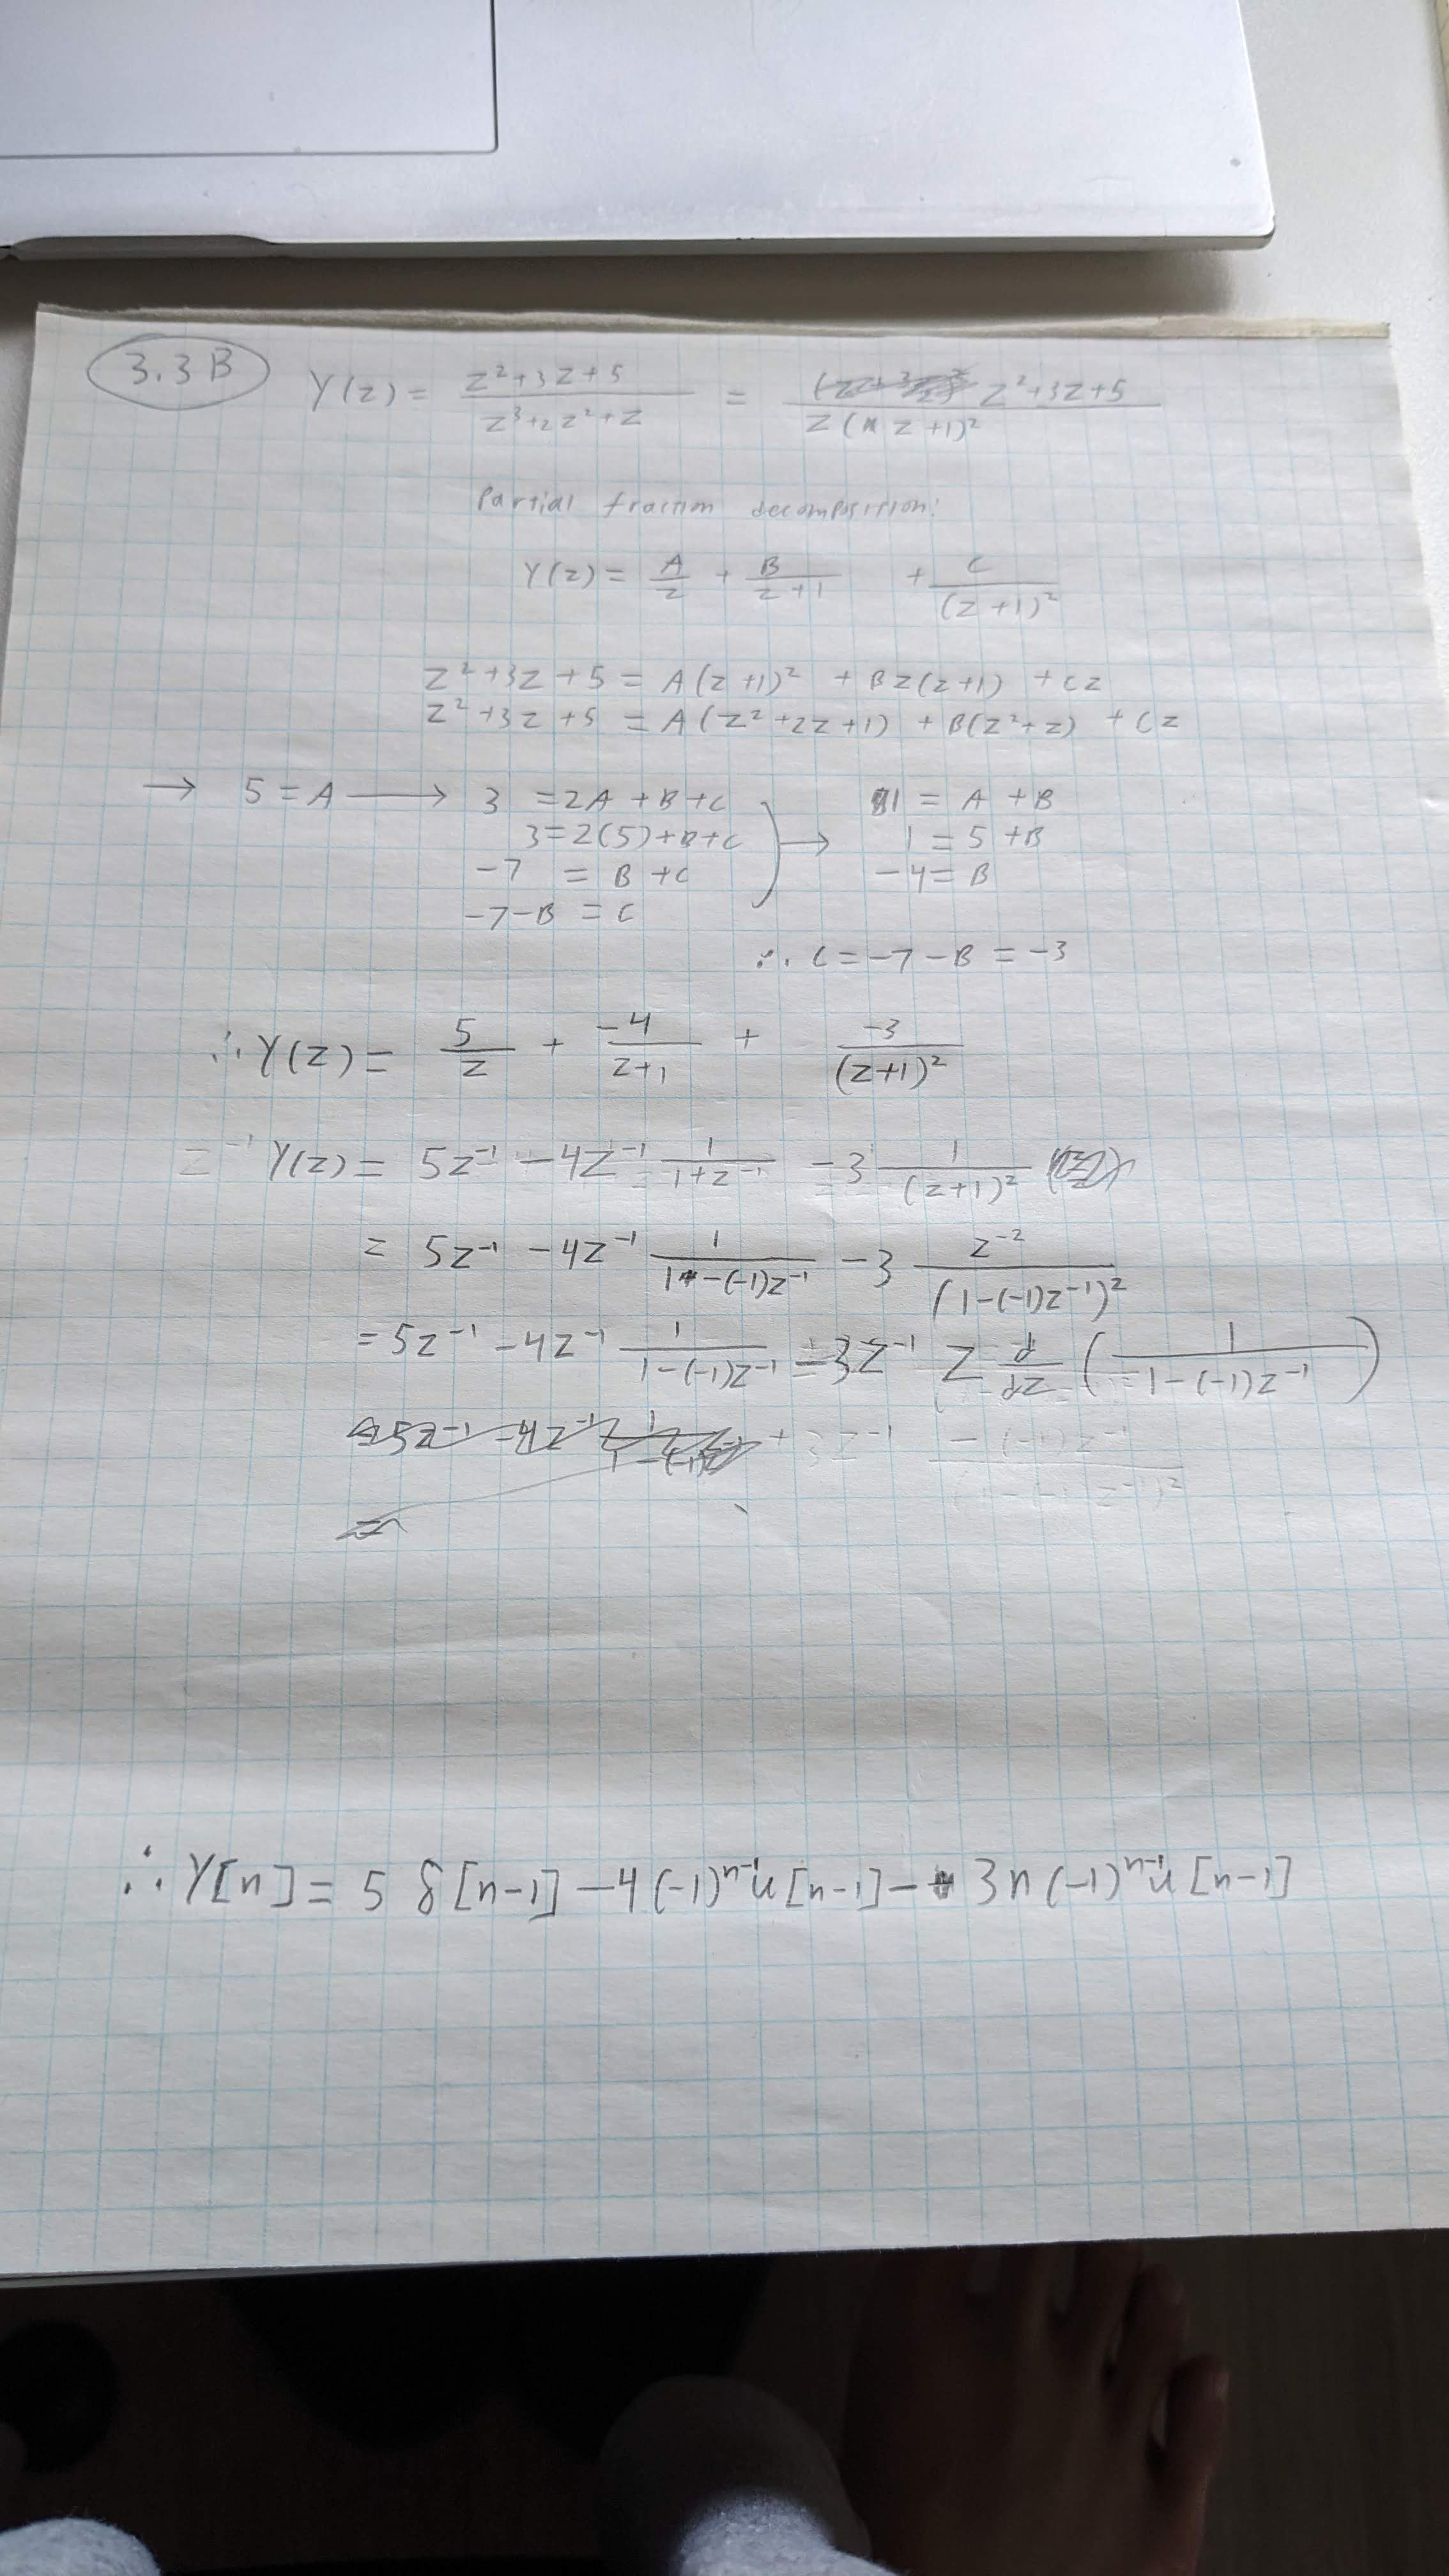

Code section:

Y = (z^2 + 3*z + 5)/(z^3 + 2*z^2 + z)

$$Y = \frac{z^{2}+3\,z+5}{z^{3}+2\,z^{2}+z}$$

Y = partfrac(Y)

$$Y = \frac{5}{z}-\frac{3}{{\left(z+1\right)}^{2}}-\frac{4}{z+1}$$

y = iztrans(Y)

$$y = 5\,\delta_{n-1,0}+4\,{\left(-1\right)}^{n}-7\,\delta_{n,0}-3\,{\left(-1\right)}^{n}\,\left(n-1\right)$$

## 3.4

Code Section to plot rabbit population from n 1 to 30:

openExample("symbolic/SolveDifferenceEquationsUsingZTransformExample");
nValues = 1:30

nValues =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


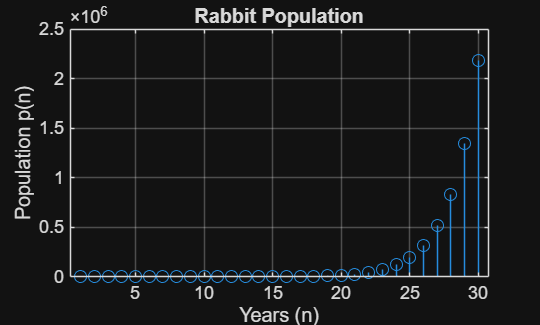

pSolValues = subs(pSol,n,nValues);
pSolValues = double(pSolValues);
pSolValues = real(pSolValues);
stem(nValues,pSolValues)
title("Rabbit Population")
xlabel("Years (n)")
ylabel("Population p(n)")
grid on

The rabbit population seems to experience explosive, exponential growth over the course of 30 years, with the population reaching 2.5 million over the course of 30 years; the difference between the tenth and thirtieth year is very large.

The z-transform was used to solve this problem by way of first defining a recursive equation and setting it to zero so that it could be defined as f, which is essentially the form of a difference equation when taken through a z-transform. 

However, since the ztrans() command can only process symbolic variables, pZT was used as a temporary placeholder for the z-transform of p(n). while in the z-domain, it was much easier to solve for pZT, as it was no longer recursive. This allowed us to then solve for its expression in the z-domain, then use iztrans() to convert it back into its very complex time-domain expression without needing to undergo complicated and time consuming calculations.